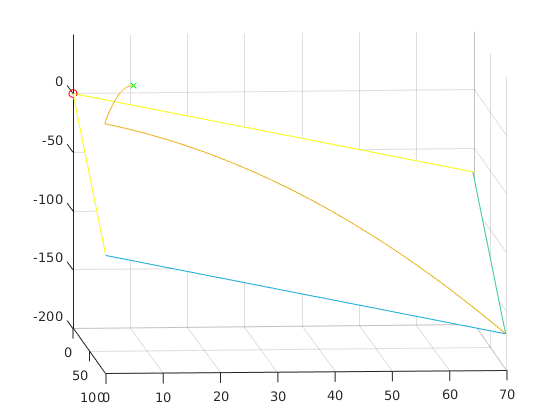

nBounces = 2;
timeout = 20; % seconds
coeff_restitution = 0.95; % unitless
g = 9.80; % m/s^2

p_0 = [10; 10; 10];
v_0 = [2; -2; 2];
normal = [1; 1; 1]; % this value may be overwritten later
origin = [0; 0; 0];

[T, States, endTimes] = bounceSim(nBounces, timeout, [p_0, v_0], coeff_restitution, origin, normal, g);
plot_bounce(States, p_0, normal);

States(T == endTimes(1), :) % the location of the first bounce

ans =    15.3737    4.6263  -20.0000    2.0000   -2.0000  -24.3311


States(T == endTimes(2), :) % this should be very close to the origin if all the math is right

ans =    99.4123   69.7959 -169.2082   17.8152   13.8152  -54.7449


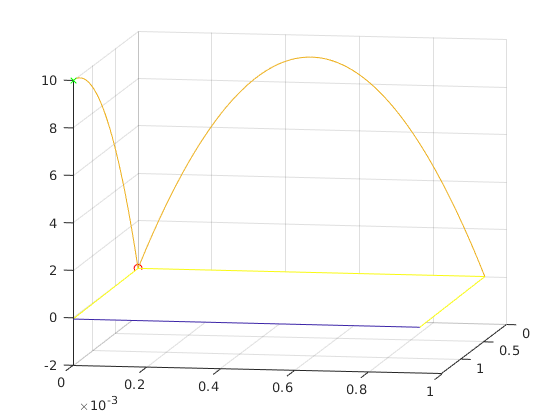

p_0 = [sqrt(2 * 10 / 9.8); 0; 10];
v_0 = [-1; 0; 0];
target = [0; 0; 0];

func_Posf_of_N = @ (N) (abs(landing_position(N, 2, 9.8, 0.95, v_0, p_0) - target));
func_XofN = @ (N) (dot(func_Posf_of_N(N), [1 0 0]));
func_YofN = @ (N) (dot(func_Posf_of_N(N), [0 1 0]));

func_DistofN = @ (N) (func_XofN(N)^2 + func_YofN(N)^2);

search_options = optimset('MaxFunEvals', 1000);
n_ideal = fminsearch(func_DistofN, [0; 0; 1], search_options);
[T, States, endTimes] = bounceSim(nBounces, timeout, [p_0, v_0], coeff_restitution, origin, n_ideal, g);
plot_bounce(States, p_0, n_ideal);

function plot_bounce(States, p_0, normal)
    figure()
    hold on;
    
    plot3(0, 0, 0, 'ro');
    plot3(p_0(1), p_0(2), p_0(3), 'gx');
    
    plot3(States(:, 1), States(:, 2), States(:, 3));
    view(100, 10);
    
    Xbounds = [min(min(States(:, 1)), 0), max(max(States(:, 1)), 0)];
    Ybounds = [min(min(States(:, 2)), 0), max(max(States(:, 2)), 0)];
    
    [X, Y] = meshgrid(Xbounds, Ybounds);
    Z = -normal(1)/normal(3) * X - normal(2)/normal(3) * Y;
    mesh(X, Y, Z);
    
    grid on
end